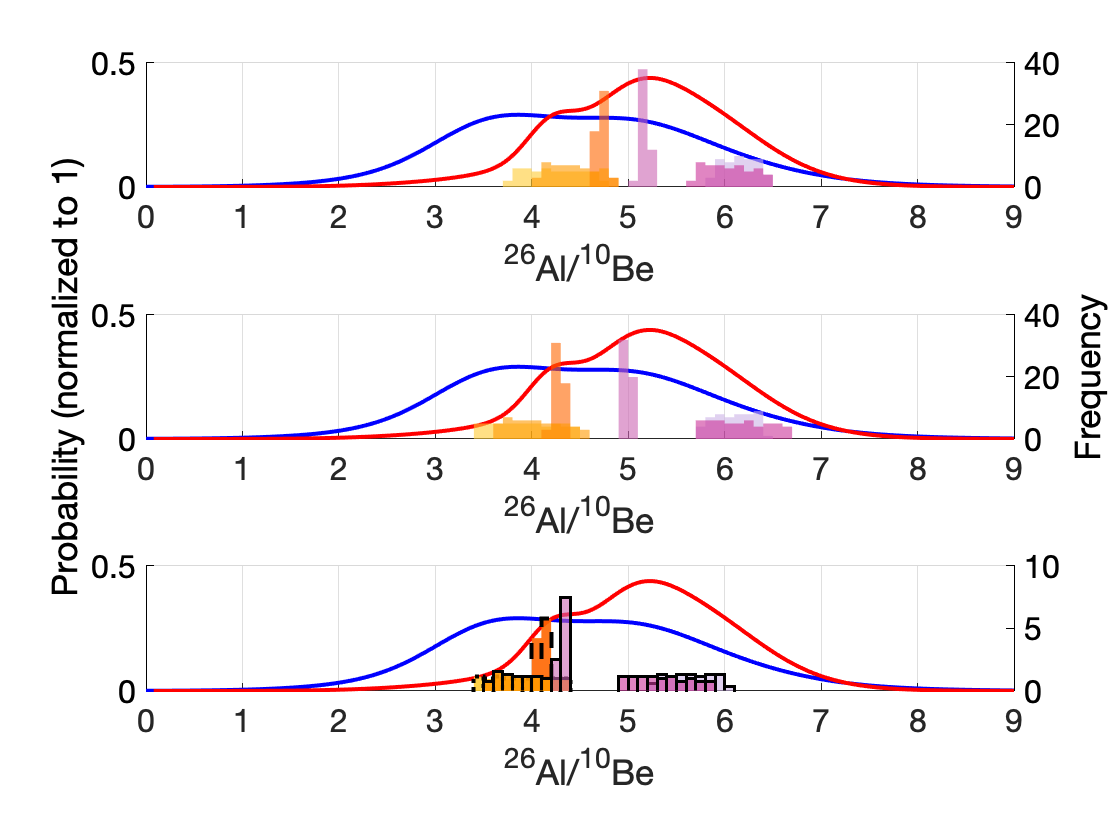

% This script generates plots shown in Fig. S1, S2, S8, & S9. All scenarios must be generated prior to running (see
% invdividual scripts).

% import real data results - please email Danielle LeBlanc
% (leblandf@bc.edu) for access to data files
[data txt] = xlsread('final_project_data.xlsx','New');
[ratios txt] = xlsread('final_project_data.xlsx','Ratios');

% 10be concs
be10_east = data(:,2);
be10_east_background = be10_east(1:2:end);
be10_east_heinrich = be10_east(2:2:end);

be10_west = data(:,4);
be10_west_background = be10_west(1:2:end);
be10_west_heinrich = be10_west(2:2:end);

east_uncert = data(:,3);
east_uncert_background = east_uncert(1:2:end);
east_uncert_heinrich = east_uncert(2:2:end);

west_uncert = data(:,5);
west_uncert_background = west_uncert(1:2:end);
west_uncert_heinrich = west_uncert(2:2:end);

% ratios
ratio_east = ratios(:,1);
ratio_east_background = ratio_east(1:2:end);
ratio_east_heinrich = ratio_east(2:2:end);

ratio_west = ratios(:,3);
ratio_west_background = ratio_west(1:2:end);
ratio_west_heinrich = ratio_west(2:2:end);

eastratio_uncert = ratios(:,2);
eastratio_uncert_background = eastratio_uncert(1:2:end);
eastratio_uncert_heinrich = eastratio_uncert(2:2:end);

westratio_uncert = ratios(:,4);
westratio_uncert_background = westratio_uncert(1:2:end);
westratio_uncert_heinrich = westratio_uncert(2:2:end);

% find outputs covering the last 60,000 years, locates upper and lower bounds for time series data
htime = time(i1:i2); 
hi1 = find(htime == 14000); % lower bound, 14 kyr
hi2 = find(htime == 65000); % upper bound, 65 kyr

% saves data from across this range for each of the scenarios run under
% different erosion rates (1, 10, 100 mm/kyr)

% EROSION RATE 2 = 10 MM/KYR (X1-X6)

X1 = savedal_ird_er2(:,1)./savedbe_ird_er2(:,1);
X1 = X1([hi2:hi1]);
X2 = savedal_ird_er2(:,2)./savedbe_ird_er2(:,2);
X2 = X2([hi2:hi1]);
X3 = savedal_ird_er2(:,5)./savedbe_ird_er2(:,5);
X3 = X3([hi2:hi1]);
X4 = savedal_ird_er2(:,6)./savedbe_ird_er2(:,6);
X4 = X4([hi2:hi1]);
X5 = savedal_ird_er2(:,7)./savedbe_ird_er2(:,7);
X5 = X5([hi2:hi1]);
X6 = savedal_ird_er2(:,8)./savedbe_ird_er2(:,8);
X6 = X6([hi2:hi1]);

% EROSION RATE 1 = 1 MM/KYR (X7-X12)

X7 = savedal_ird_er1(:,1)./savedbe_ird_er1(:,1);
X7 = X7([hi2:hi1]);
X8 = savedal_ird_er1(:,2)./savedbe_ird_er1(:,2);
X8 = X8([hi2:hi1]);
X9 = savedal_ird_er1(:,5)./savedbe_ird_er1(:,5);
X9 = X9([hi2:hi1]);
X10 = savedal_ird_er1(:,6)./savedbe_ird_er1(:,6);
X10 = X10([hi2:hi1]);
X11 = savedal_ird_er1(:,7)./savedbe_ird_er1(:,7);
X11 = X11([hi2:hi1]);
X12 = savedal_ird_er1(:,8)./savedbe_ird_er1(:,8);
X12 = X12([hi2:hi1]);

% EROSION RATE 3 = 100 MM/KYR (X13-X18)

X13 = savedal_ird_er3(:,1)./savedbe_ird_er3(:,1);
X13 = X13([hi2:hi1]);
X14 = savedal_ird_er3(:,2)./savedbe_ird_er3(:,2);
X14 = X14([hi2:hi1]);
X15 = savedal_ird_er3(:,5)./savedbe_ird_er3(:,5);
X15 = X15([hi2:hi1]);
X16 = savedal_ird_er3(:,6)./savedbe_ird_er3(:,6);
X16 = X16([hi2:hi1]);
X17 = savedal_ird_er3(:,7)./savedbe_ird_er3(:,7);
X17 = X17([hi2:hi1]);
X18 = savedal_ird_er3(:,8)./savedbe_ird_er3(:,8);
X18 = X18([hi2:hi1]);

% figure 3 - 3 histograms showing ratios for 1-and 10-kyr interglacials for three
% scenarios: (1) frequent-interglacial scenario, (2) skipped-interglacial scenario, (3) skipped
% with doubling of early Pleistocene exposure 

figure
subplot(3,1,1)
yyaxis left
camelplot_v2(ratio_west, westratio_uncert);
hold on
camelplot(ratio_east, eastratio_uncert);
set(gca,'YColor','k')
hold on
yyaxis right
histogram(X1,'FaceColor',[1 0.8 0.2],'EdgeColor','none','BinWidth',0.1) 
histogram(X7,'FaceColor',[1 0.4 0],'EdgeColor','none','BinWidth',0.1) 
histogram(X13,'FaceColor',[1 0.6 0],'EdgeColor','none','BinWidth',0.1)
histogram(X2,'FaceColor',[0.8 0.7 0.9],'EdgeColor','none','BinWidth',0.1)  
histogram(X8,'FaceColor',[0.8 0.4 0.7],'EdgeColor','none','BinWidth',0.1)  
histogram(X14,'FaceColor',[0.8 0.2 0.6],'EdgeColor','none','BinWidth',0.1)  
xlim([0 9])
xlabel('^{26}Al/^{10}Be','FontSize',20)
set(gca,'YColor','k','FontSize',16)
hold off

subplot(3,1,2)
yyaxis left
camelplot_v2(ratio_west, westratio_uncert);
hold on
camelplot(ratio_east, eastratio_uncert);
ylabel('Probability (normalized to 1)','FontSize',20)
set(gca,'YColor','k')
hold on
yyaxis right
histogram(X3,'FaceColor',[1 0.8 0.2],'EdgeColor','none','BinWidth',0.1) 
histogram(X9,'FaceColor',[1 0.4 0],'EdgeColor','none','BinWidth',0.1) 
histogram(X15,'FaceColor',[1 0.6 0],'EdgeColor','none','BinWidth',0.1) 
histogram(X4,'FaceColor',[0.8 0.7 0.9],'EdgeColor','none','BinWidth',0.1)   
histogram(X10,'FaceColor',[0.8 0.4 0.7],'EdgeColor','none','BinWidth',0.1)  
histogram(X16,'FaceColor',[0.8 0.2 0.6],'EdgeColor','none','BinWidth',0.1)  
xlim([0 9])
xlabel('^{26}Al/^{10}Be','FontSize',20)
ylabel('Frequency','FontSize',20)
set(gca,'YColor','k','FontSize',16)
hold off

subplot(3,1,3)
yyaxis left
camelplot_v2(ratio_west, westratio_uncert);
hold on
camelplot(ratio_east, eastratio_uncert);
set(gca,'YColor','k')
hold on
yyaxis right
histogram(X5,'FaceColor',[1 0.8 0.2],'EdgeColor','none','BinWidth',0.1) 
histogram(X11,'FaceColor',[1 0.4 0],'EdgeColor','none','BinWidth',0.1) 
histogram(X17,'FaceColor',[1 0.6 0],'EdgeColor','none','BinWidth',0.1) 
histogram(X6,'FaceColor',[0.8 0.7 0.9],'EdgeColor','none','BinWidth',0.1)   
histogram(X12,'FaceColor',[0.8 0.4 0.7],'EdgeColor','none','BinWidth',0.1)   
histogram(X18,'FaceColor',[0.8 0.2 0.6],'EdgeColor','none','BinWidth',0.1)
xlim([0 9])
xlabel('^{26}Al/^{10}Be','FontSize',20)
set(gca,'YColor','k','FontSize',16)
hold off

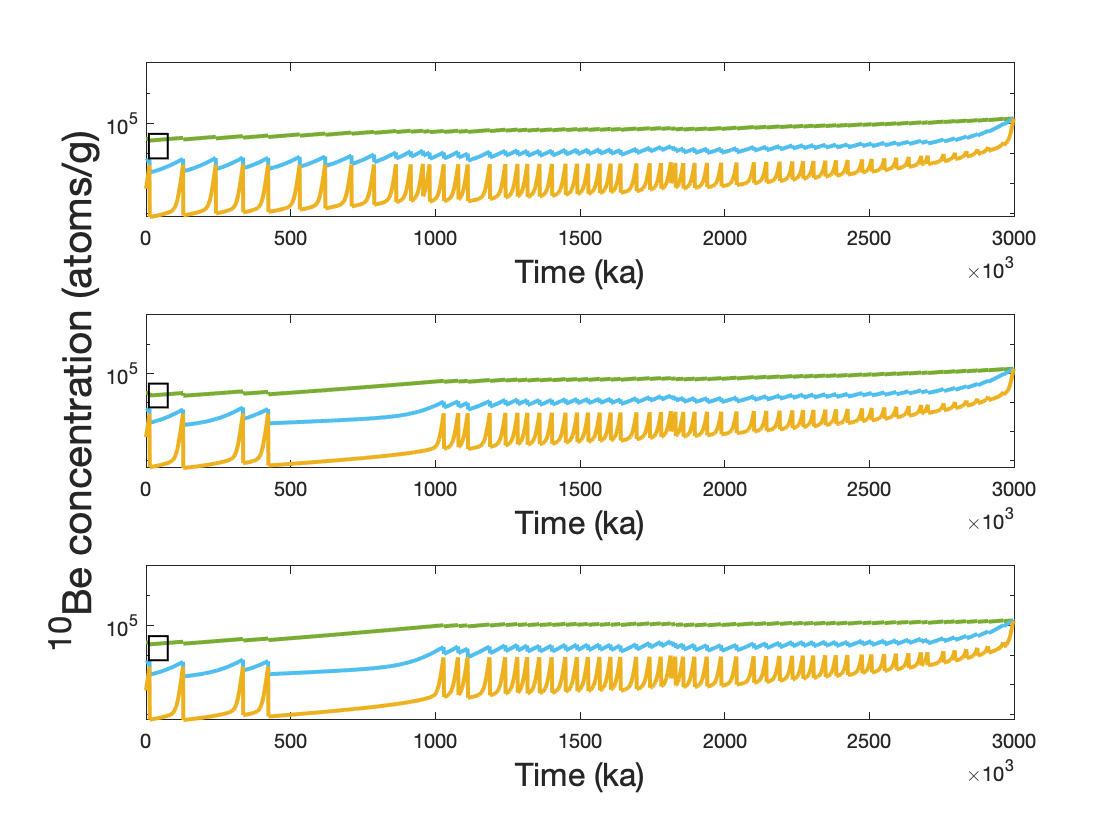


% extended data figure 9 - 10be concentrations and 26/10 ratios for all
% three scenarios using all erosion rates (1, 10, 100 mm/kyr) with 1-kyr IG

% plots 10be concentrations for 1-kyr IG
figure 
subplot(3,1,1)
semilogy(time(i1:i2),savedbe_surf_er1(:,1),'Color',[0.4660 0.6740 0.1880],'LineWidth',2)
hold on
semilogy(time(i1:i2),savedbe_surf_er2(:,1),'Color',[0.3010 0.7450 0.9330], 'LineWidth',2)
semilogy(time(i1:i2),savedbe_surf_er3(:,1),'Color',[0.9290 0.6940 0.1250], 'LineWidth',2)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
xlim([0 3e6])
h = rectangle('Position',[10000,min([be10_east; be10_west]),65000,max([be10_east; be10_west])-min([be10_east; be10_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
ylim([0 1e7])
hold off

subplot(3,1,2)
semilogy(time(i1:i2),savedbe_surf_er1(:,5),'Color',[0.4660 0.6740 0.1880],'LineWidth',2)
hold on
semilogy(time(i1:i2),savedbe_surf_er2(:,5),'Color',[0.3010 0.7450 0.9330], 'LineWidth',2)
semilogy(time(i1:i2),savedbe_surf_er3(:,5),'Color',[0.9290 0.6940 0.1250], 'LineWidth',2)
ylabel('^{10}Be concentration (atoms/g)','FontSize',20)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
xlim([0 3e6])
h = rectangle('Position',[10000,min([be10_east; be10_west]),65000,max([be10_east; be10_west])-min([be10_east; be10_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
ylim([0 1e7])
hold off

subplot(3,1,3)
semilogy(time(i1:i2),savedbe_surf_er1(:,7),'Color',[0.4660 0.6740 0.1880],'LineWidth',2)
hold on
semilogy(time(i1:i2),savedbe_surf_er2(:,7),'Color',[0.3010 0.7450 0.9330], 'LineWidth',2)
semilogy(time(i1:i2),savedbe_surf_er3(:,7),'Color',[0.9290 0.6940 0.1250], 'LineWidth',2)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
xlim([0 3e6])
h = rectangle('Position',[10000,min([be10_east; be10_west]),65000,max([be10_east; be10_west])-min([be10_east; be10_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
ylim([0 1e7])
hold off

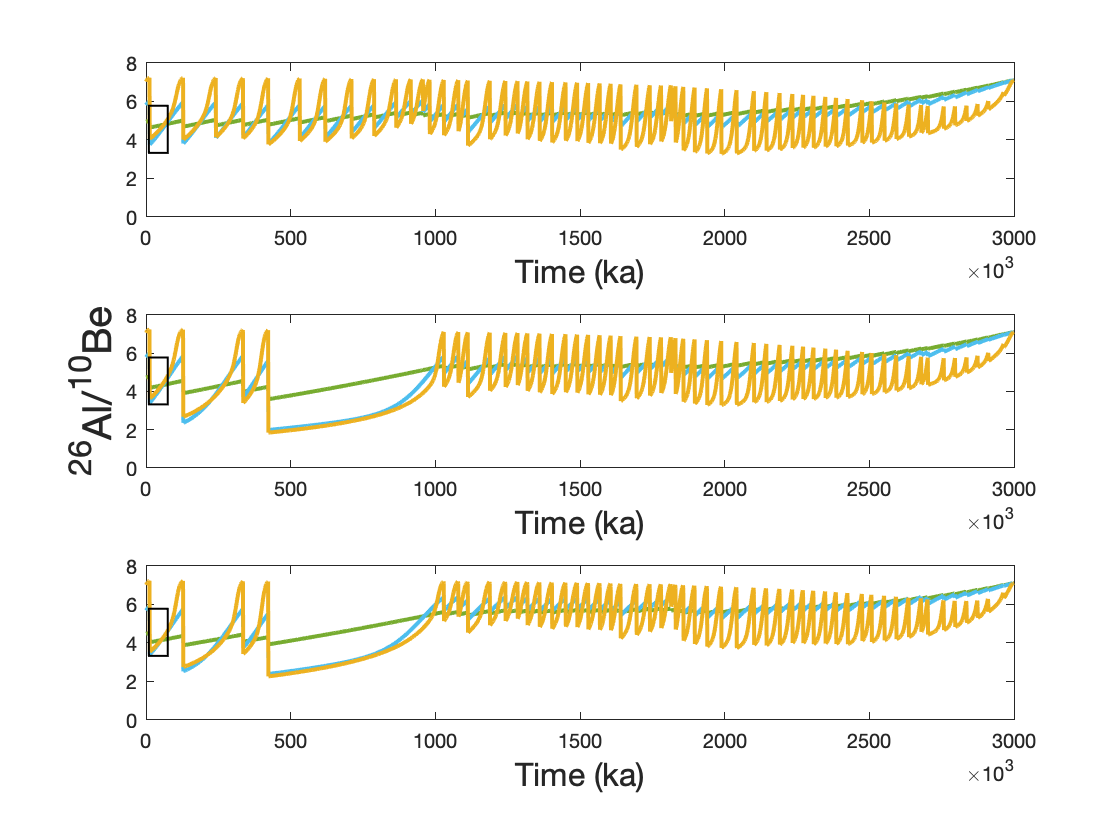


% plots 26/10 ratios for 1-kyr IG
figure 
subplot(3,1,1)
plot(time(i1:i2),savedal_surf_er1(:,1)./savedbe_surf_er1(:,1),'Color',[0.4660 0.6740 0.1880],'LineWidth',2)
hold on
plot(time(i1:i2),savedal_surf_er2(:,1)./savedbe_surf_er2(:,1),'Color',[0.3010 0.7450 0.9330], 'LineWidth',2)
plot(time(i1:i2),savedal_surf_er3(:,1)./savedbe_surf_er3(:,1),'Color',[0.9290 0.6940 0.1250], 'LineWidth',2)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
xlim([0 3e6])
ylim([0 8])
h = rectangle('Position',[10000,min([ratio_east; ratio_west]),65000,max([ratio_east; ratio_west])-min([ratio_east; ratio_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
hold off

subplot(3,1,2)
plot(time(i1:i2),savedal_surf_er1(:,5)./savedbe_surf_er1(:,5),'Color',[0.4660 0.6740 0.1880],'LineWidth',2)
hold on
plot(time(i1:i2),savedal_surf_er2(:,5)./savedbe_surf_er2(:,5),'Color',[0.3010 0.7450 0.9330], 'LineWidth',2)
plot(time(i1:i2),savedal_surf_er3(:,5)./savedbe_surf_er3(:,5),'Color',[0.9290 0.6940 0.1250], 'LineWidth',2)
ylabel('^{26}Al/^{10}Be','FontSize',20)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
ylim([0 8])
xlim([0 3e6 ])
h = rectangle('Position',[10000,min([ratio_east; ratio_west]),65000,max([ratio_east; ratio_west])-min([ratio_east; ratio_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
hold off

subplot(3,1,3)
plot(time(i1:i2),savedal_surf_er1(:,7)./savedbe_surf_er1(:,7),'Color',[0.4660 0.6740 0.1880],'LineWidth',2)
hold on
plot(time(i1:i2),savedal_surf_er2(:,7)./savedbe_surf_er2(:,7),'Color',[0.3010 0.7450 0.9330], 'LineWidth',2)
plot(time(i1:i2),savedal_surf_er3(:,7)./savedbe_surf_er3(:,7),'Color',[0.9290 0.6940 0.1250], 'LineWidth',2)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
ylim([0 8])
h = rectangle('Position',[10000,min([ratio_east; ratio_west]),65000,max([ratio_east; ratio_west])-min([ratio_east; ratio_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
hold off

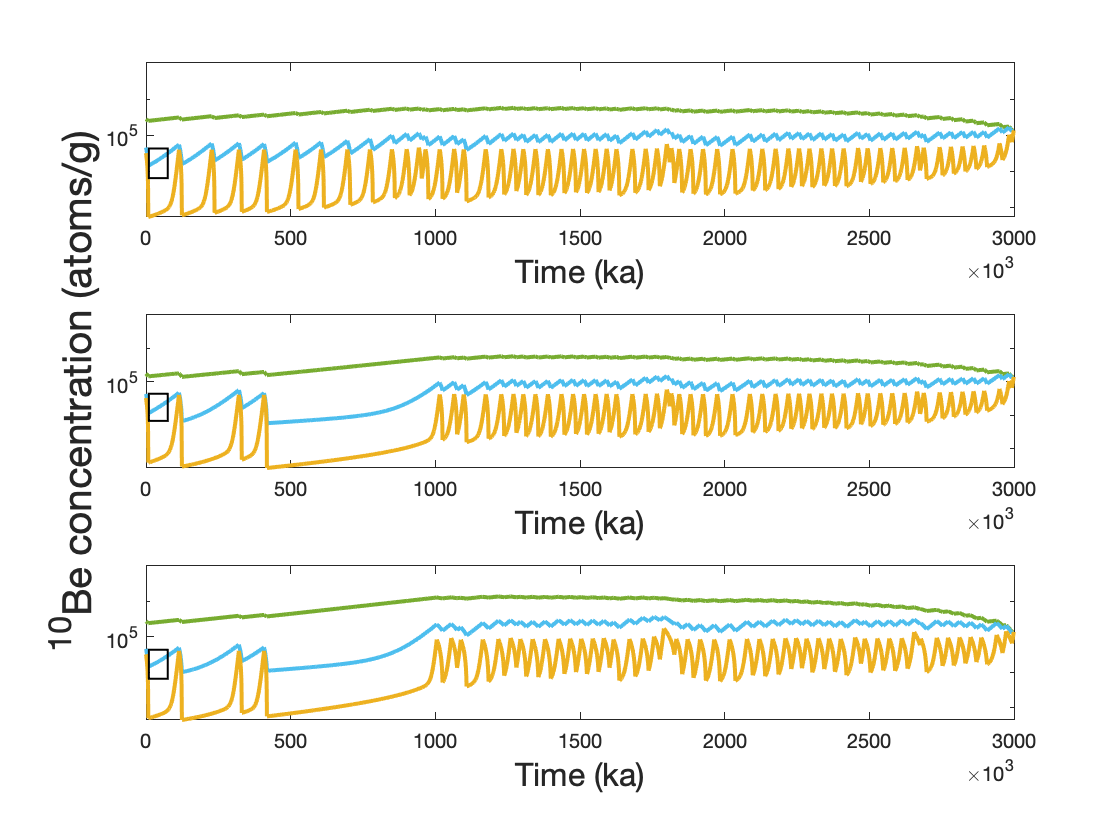


% extended data figure 10 - 10be concentrations and 26/10 ratios for all
% three scenarios using all erosion rates (1, 10, 100 mm/kyr) with 10-kyr IG


% plots 10be concentrations for 10-kyr IG
figure 
subplot(3,1,1)
semilogy(time(i1:i2),savedbe_surf_er1(:,2),'Color',[0.4660 0.6740 0.1880],'LineWidth',2)
hold on
semilogy(time(i1:i2),savedbe_surf_er2(:,2),'Color',[0.3010 0.7450 0.9330], 'LineWidth',2)
semilogy(time(i1:i2),savedbe_surf_er3(:,2),'Color',[0.9290 0.6940 0.1250], 'LineWidth',2)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
xlim([0 3e6])
h = rectangle('Position',[10000,min([be10_east; be10_west]),65000,max([be10_east; be10_west])-min([be10_east; be10_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
ylim([0 1e7])
hold off

subplot(3,1,2)
semilogy(time(i1:i2),savedbe_surf_er1(:,6),'Color',[0.4660 0.6740 0.1880],'LineWidth',2)
hold on
semilogy(time(i1:i2),savedbe_surf_er2(:,6),'Color',[0.3010 0.7450 0.9330], 'LineWidth',2)
semilogy(time(i1:i2),savedbe_surf_er3(:,6),'Color',[0.9290 0.6940 0.1250], 'LineWidth',2)
ylabel('^{10}Be concentration (atoms/g)','FontSize',20)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
xlim([0 3e6])
h = rectangle('Position',[10000,min([be10_east; be10_west]),65000,max([be10_east; be10_west])-min([be10_east; be10_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
ylim([0 1e7])
hold off

subplot(3,1,3)
semilogy(time(i1:i2),savedbe_surf_er1(:,8),'Color',[0.4660 0.6740 0.1880],'LineWidth',2)
hold on
semilogy(time(i1:i2),savedbe_surf_er2(:,8),'Color',[0.3010 0.7450 0.9330], 'LineWidth',2)
semilogy(time(i1:i2),savedbe_surf_er3(:,8),'Color',[0.9290 0.6940 0.1250], 'LineWidth',2)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
xlim([0 3e6])
h = rectangle('Position',[10000,min([be10_east; be10_west]),65000,max([be10_east; be10_west])-min([be10_east; be10_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
ylim([0 1e7])
hold off

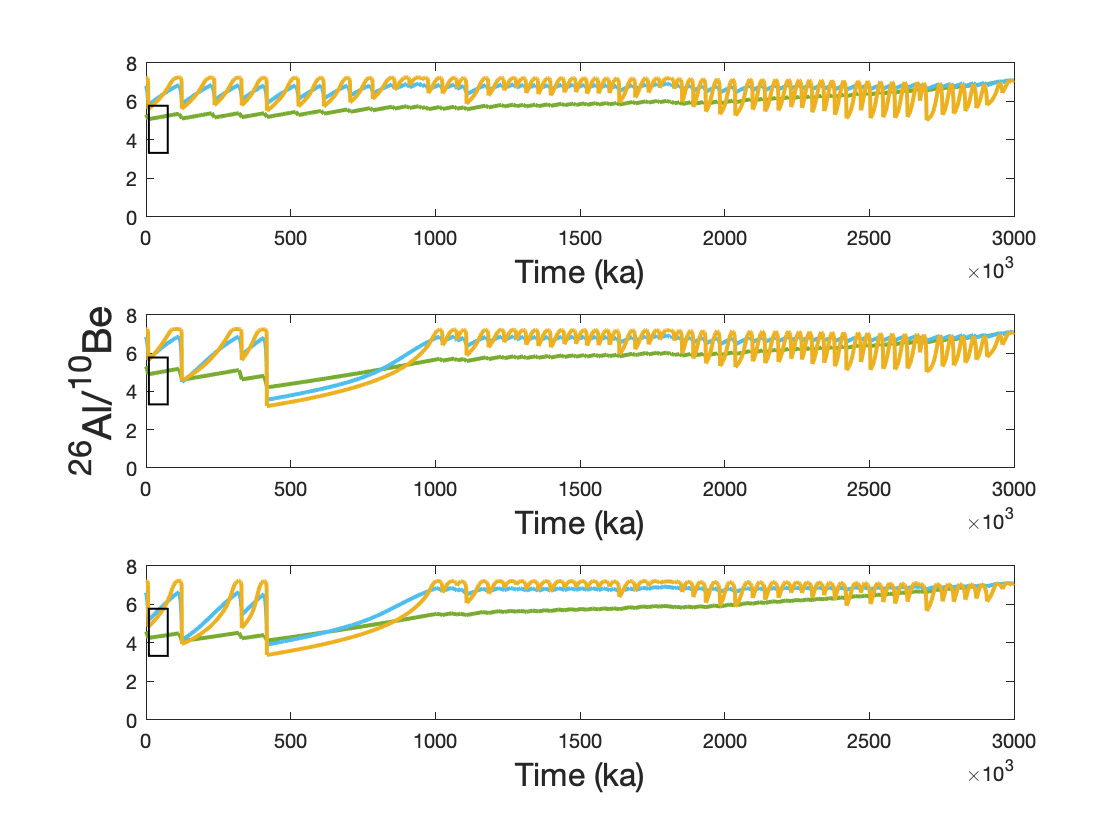


% plots 26/10 ratios for 10-kyr IG

figure 
subplot(3,1,1)
plot(time(i1:i2),savedal_surf_er1(:,2)./savedbe_surf_er1(:,2),'Color',[0.4660 0.6740 0.1880],'LineWidth',2)
hold on
plot(time(i1:i2),savedal_surf_er2(:,2)./savedbe_surf_er2(:,2),'Color',[0.3010 0.7450 0.9330], 'LineWidth',2)
plot(time(i1:i2),savedal_surf_er3(:,2)./savedbe_surf_er3(:,2),'Color',[0.9290 0.6940 0.1250], 'LineWidth',2)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
xlim([0 3e6])
ylim([0 8])
h = rectangle('Position',[10000,min([ratio_east; ratio_west]),65000,max([ratio_east; ratio_west])-min([ratio_east; ratio_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
hold off

subplot(3,1,2)
plot(time(i1:i2),savedal_surf_er1(:,6)./savedbe_surf_er1(:,6),'Color',[0.4660 0.6740 0.1880],'LineWidth',2)
hold on
plot(time(i1:i2),savedal_surf_er2(:,6)./savedbe_surf_er2(:,6),'Color',[0.3010 0.7450 0.9330], 'LineWidth',2)
plot(time(i1:i2),savedal_surf_er3(:,6)./savedbe_surf_er3(:,6),'Color',[0.9290 0.6940 0.1250], 'LineWidth',2)
ylabel('^{26}Al/^{10}Be','FontSize',20)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
ylim([0 8])
xlim([0 3e6 ])
h = rectangle('Position',[10000,min([ratio_east; ratio_west]),65000,max([ratio_east; ratio_west])-min([ratio_east; ratio_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
hold off

subplot(3,1,3)
plot(time(i1:i2),savedal_surf_er1(:,8)./savedbe_surf_er1(:,8),'Color',[0.4660 0.6740 0.1880],'LineWidth',2)
hold on
plot(time(i1:i2),savedal_surf_er2(:,8)./savedbe_surf_er2(:,8),'Color',[0.3010 0.7450 0.9330], 'LineWidth',2)
plot(time(i1:i2),savedal_surf_er3(:,8)./savedbe_surf_er3(:,8),'Color',[0.9290 0.6940 0.1250], 'LineWidth',2)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
ylim([0 8])
h = rectangle('Position',[10000,min([ratio_east; ratio_west]),65000,max([ratio_east; ratio_west])-min([ratio_east; ratio_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
hold off

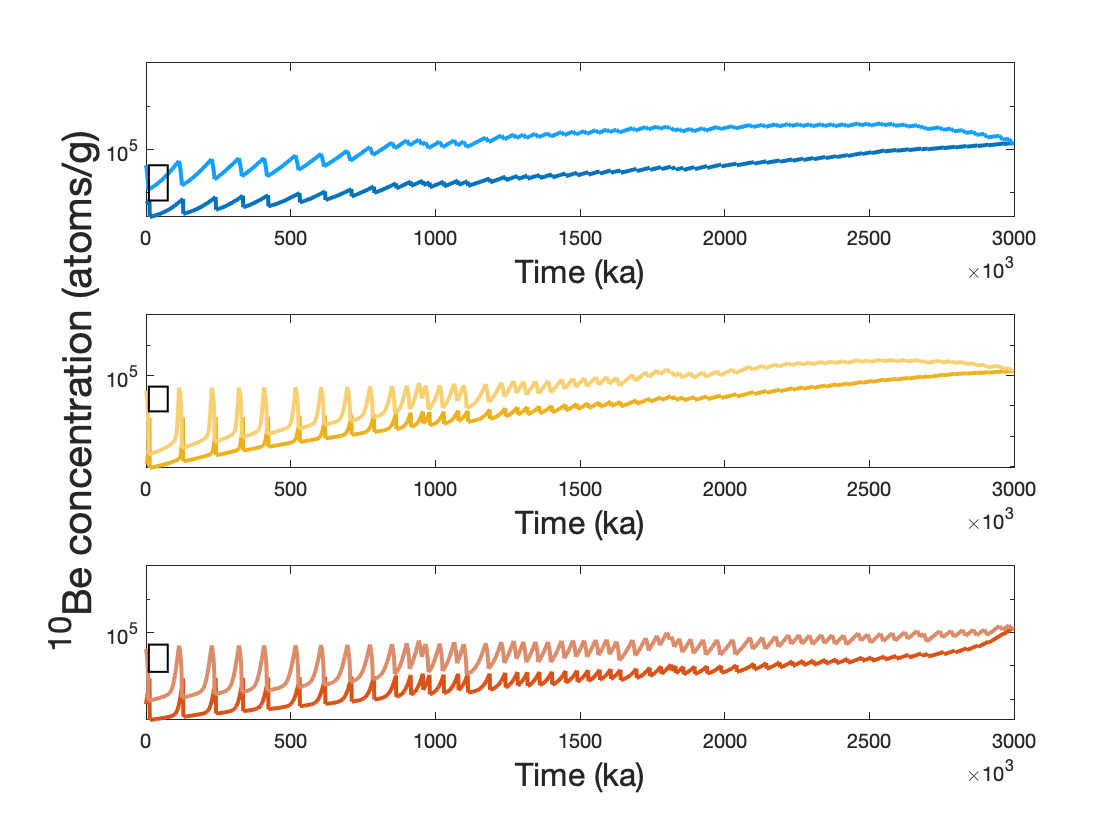


% extended data figure 1 - 10be concentrations and 26/10 ratios for all
% three acceleration scenarios using 1 and 10- kyr IG

% plots 10be concentrations for 1-and-10 kyr IG
figure 
subplot(3,1,1)
semilogy(time(i1:i2),savedbe_surf_er1(:,9),'Color',[0    0.4471    0.7412],'LineWidth',2)
hold on
semilogy(time(i1:i2),savedbe_surf_er1(:,12),'Color',[0.0745    0.6235    1.0000], 'LineWidth',2)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
xlim([0 3e6])
h = rectangle('Position',[10000,min([be10_east; be10_west]),65000,max([be10_east; be10_west])-min([be10_east; be10_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
ylim([0 1e7])
hold off

subplot(3,1,2)
semilogy(time(i1:i2),savedbe_surf_er1(:,10),'Color',[0.9294    0.6941    0.1255],'LineWidth',2)
hold on
semilogy(time(i1:i2),savedbe_surf_er1(:,13),'Color',[0.9686    0.8157    0.4549], 'LineWidth',2)
ylabel('^{10}Be concentration (atoms/g)','FontSize',20)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
xlim([0 3e6])
h = rectangle('Position',[10000,min([be10_east; be10_west]),65000,max([be10_east; be10_west])-min([be10_east; be10_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
ylim([0 1e7])
hold off

subplot(3,1,3)
semilogy(time(i1:i2),savedbe_surf_er1(:,11),'Color',[0.8510    0.3255    0.0980],'LineWidth',2)
hold on
semilogy(time(i1:i2),savedbe_surf_er1(:,14),'Color',[0.8588    0.5529    0.4196], 'LineWidth',2)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
xlim([0 3e6])
h = rectangle('Position',[10000,min([be10_east; be10_west]),65000,max([be10_east; be10_west])-min([be10_east; be10_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
ylim([0 1e7])
hold off

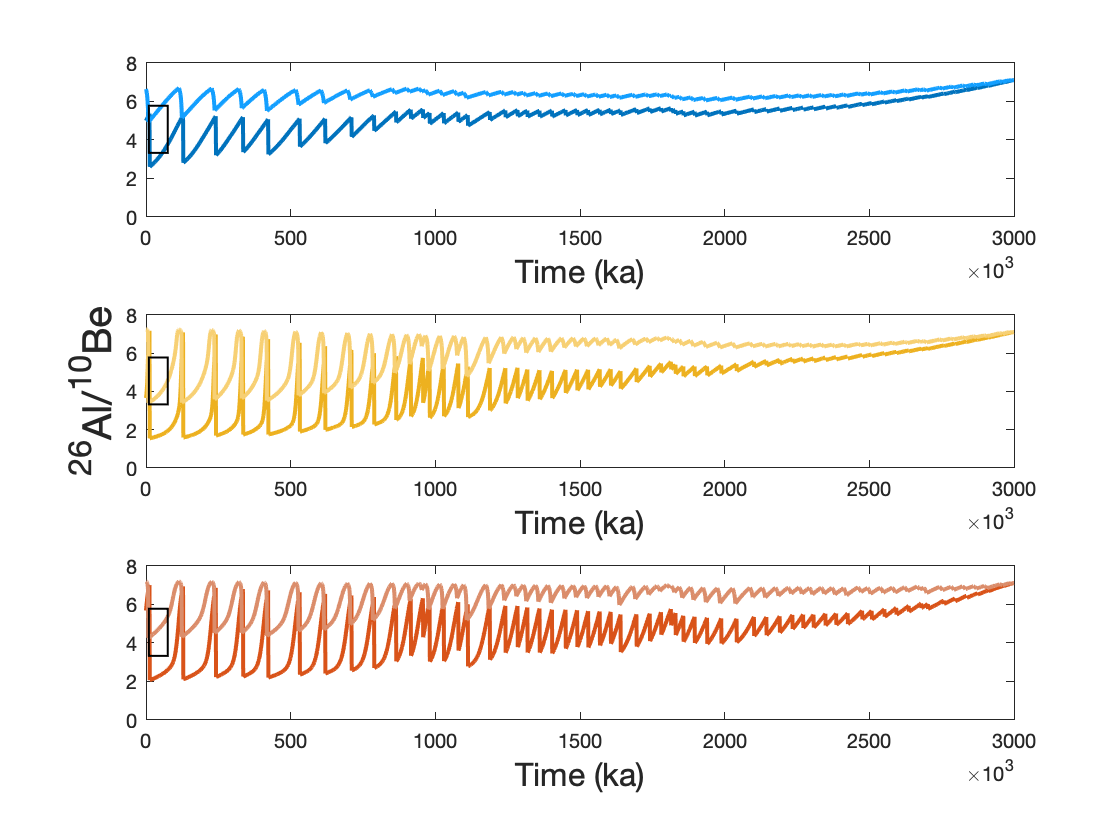


% plots 26/10 ratios for 1-and-10 kyr IG

figure 
subplot(3,1,1)
plot(time(i1:i2),savedal_surf_er1(:,9)./savedbe_surf_er1(:,9),'Color',[0    0.4471    0.7412],'LineWidth',2)
hold on
plot(time(i1:i2),savedal_surf_er1(:,12)./savedbe_surf_er1(:,12),'Color',[0.0745    0.6235    1.0000], 'LineWidth',2)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
xlim([0 3e6])
ylim([0 8])
h = rectangle('Position',[10000,min([ratio_east; ratio_west]),65000,max([ratio_east; ratio_west])-min([ratio_east; ratio_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
hold off

subplot(3,1,2)
plot(time(i1:i2),savedal_surf_er1(:,10)./savedbe_surf_er1(:,10),'Color',[0.9294    0.6941    0.1255],'LineWidth',2)
hold on
plot(time(i1:i2),savedal_surf_er1(:,13)./savedbe_surf_er1(:,13),'Color',[0.9686    0.8157    0.4549], 'LineWidth',2)
ylabel('^{26}Al/^{10}Be','FontSize',20)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
ylim([0 8])
xlim([0 3e6 ])
h = rectangle('Position',[10000,min([ratio_east; ratio_west]),65000,max([ratio_east; ratio_west])-min([ratio_east; ratio_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
hold off

subplot(3,1,3)
plot(time(i1:i2),savedal_surf_er1(:,11)./savedbe_surf_er1(:,11),'Color',[0.8510    0.3255    0.0980],'LineWidth',2)
hold on
plot(time(i1:i2),savedal_surf_er1(:,14)./savedbe_surf_er1(:,14),'Color',[0.8588    0.5529    0.4196], 'LineWidth',2)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
ylim([0 8])
h = rectangle('Position',[10000,min([ratio_east; ratio_west]),65000,max([ratio_east; ratio_west])-min([ratio_east; ratio_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
hold off

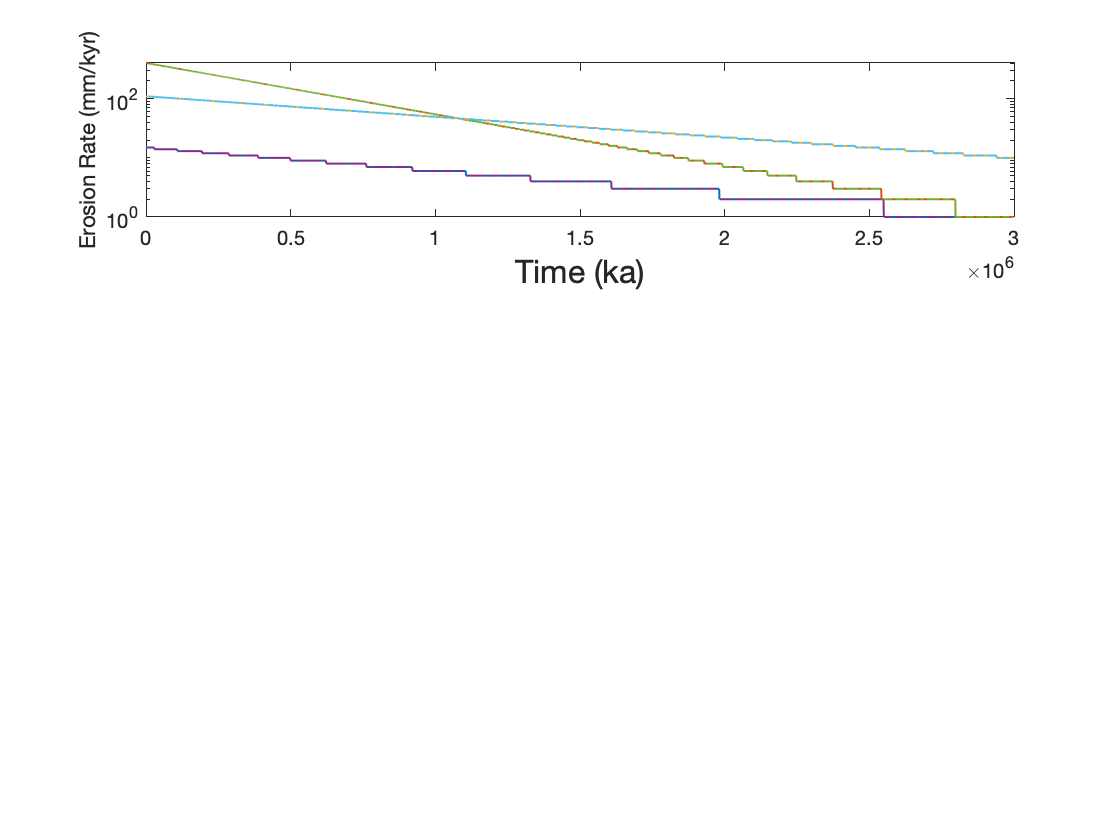


figure 
subplot(3,1,1)
semilogy(time(i1:i2),erosionrate_saved(:,[9:14]),'LineWidth',1)
hold on
xlim([0 3e6 ])
ylabel('Erosion Rate (mm/kyr)')
xlabel('Time (ka)','FontSize',16)
hold off

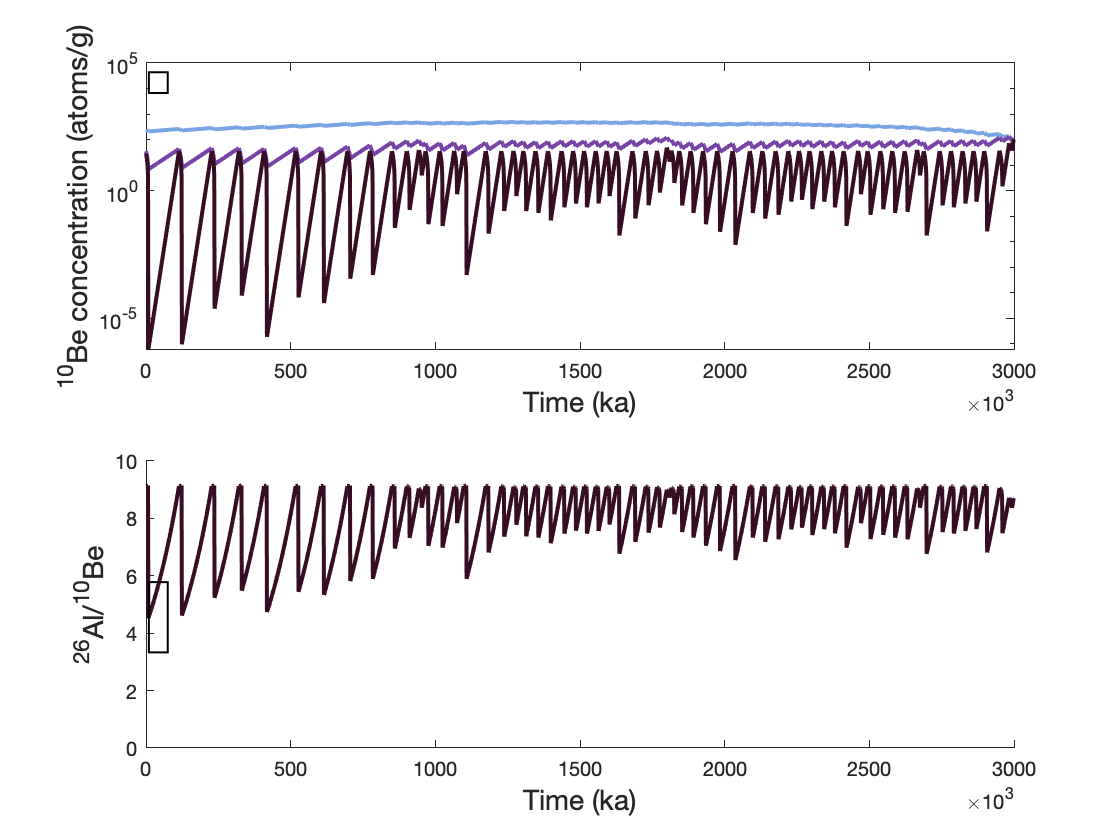


% extended data figure 11 - 10be concentrations and 26/10 ratios for
% frequent-interglacial scenario with 10-kyr IG and muon production through
% 10 meters of ice during glacial times

cmap = cmocean('dense',4); % uses cmocean colors
figure 
subplot(2,1,1)
semilogy(time(i1:i2),savedbe_surf_er1(:,15),'Color',cmap(2,:), 'LineWidth',2)
hold on
semilogy(time(i1:i2),savedbe_surf_er2(:,15),'Color',cmap(3,:), 'LineWidth',2)
semilogy(time(i1:i2),savedbe_surf_er3(:,15),'Color',cmap(4,:), 'LineWidth',2)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
xlim([0 3e6])
h = rectangle('Position',[10000,min([be10_east; be10_west]),65000,max([be10_east; be10_west])-min([be10_east; be10_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
ylim([0 1e5])
ylabel('^{10}Be concentration (atoms/g)','FontSize',14)
xlabel('Time (ka)','FontSize',14)
hold off

subplot(2,1,2)
plot(time(i1:i2),savedal_surf_er1(:,15)./savedbe_surf_er1(:,15),'Color',cmap(2,:),'LineWidth',2)
hold on
plot(time(i1:i2),savedal_surf_er2(:,15)./savedbe_surf_er2(:,15),'Color',cmap(3,:), 'LineWidth',2)
plot(time(i1:i2),savedal_surf_er3(:,15)./savedbe_surf_er3(:,15),'Color',cmap(4,:), 'LineWidth',2)
xlabel('Time (ka)','FontSize',16)
ax = gca;
ax.XAxis.Exponent = 3;
xtickformat('%.0f')
xlim([0 3e6])
ylim([0 10])
h = rectangle('Position',[10000,min([ratio_east; ratio_west]),65000,max([ratio_east; ratio_west])-min([ratio_east; ratio_west])]);
h.EdgeColor = 'k';
h.LineWidth = 1;
ylabel('^{26}Al/^{10}Be','FontSize',14)
xlabel('Time (ka)','FontSize',14)
hold off